# Demo: Reinforcement learning for Financial Trading

The example is to show the use of Multi-Agent Reinforcement Learning for Financial Trading. In this example, agents compete to outperform each other. They are rewarded when they outcompete the other, and penalized when they underperform. 

## Building constant variables

Simulate the closing prices of 3 stocks with $20,000 in 15 years. Split the data into the training data and test data. Use 12 years as the training data. 

% Simulate stock data
[trainData,testData] = simulateStockData;
numAgents = 3;
rng(2, 'twister')

## Action vectors creation

Action Combinations for stocks: Each agent has 27 possible actions, Action_vectors = [0,0,0; 0,0,1;...;2,2,2]; In this vector, $0$ represents sell; $1$ represents hold; $2$ represents buy.

x = 0:1:2;
y = 0:1:2;
z = 0:1:2;
[X,Y,Z] = meshgrid(x,y,z);
for i = 1:numel(X)
    Action_Vectors(i,:) = [Z(i),X(i),Y(i)];
end

## Reset and step function creation

Create Reset function, which defines the intitial observation for each agent, and the Step function, which takes in a vector of actions and returns the reward for each agent as well as their new observation.

ResetHandle = @() myResetFunctionMulti(trainData, numAgents);
StepHandle = @(Actions,StockSaved) myStepFunctionMulti(Actions,StockSaved,trainData,Action_Vectors,true, numAgents);

## Observation Definition

The input for each agent is 19 values, which map to the observation vector: 

- 3 x Stocks owned

- 3 x Price difference from when bought

- 1 x Cash in hand

- 3 x Price change from yesterday

- 3 x Price change from 2 days ago

- 3 x Price change from 7 days ago

- 3 x Price change from average price of 7 days ago

ObservationInfo = cell(1, numAgents);
for i=1:numAgents 
    obs = rlNumericSpec([1 19]);
    obs.Description = ['stockholdings, ', ...
        'stock buy price difference, ', ' cash, ', 'StockInd1, ' , 'StockInd2, ', 'StockInd3 '];
    ObservationInfo(i) = { obs };
end

## Action definition

ActionInfo = cell(1, numAgents);
for i=1:numAgents  
    act = rlFiniteSetSpec(1:27);
    act.Name = 'Stock Actions';
    ActionInfo(i) = { act };
end

## Environment creation

Create environment in which the agent acts

env = rlMultiAgentFunctionEnv(ObservationInfo,ActionInfo,StepHandle,ResetHandle);

## Creation of the PPO Agents

Neural networks

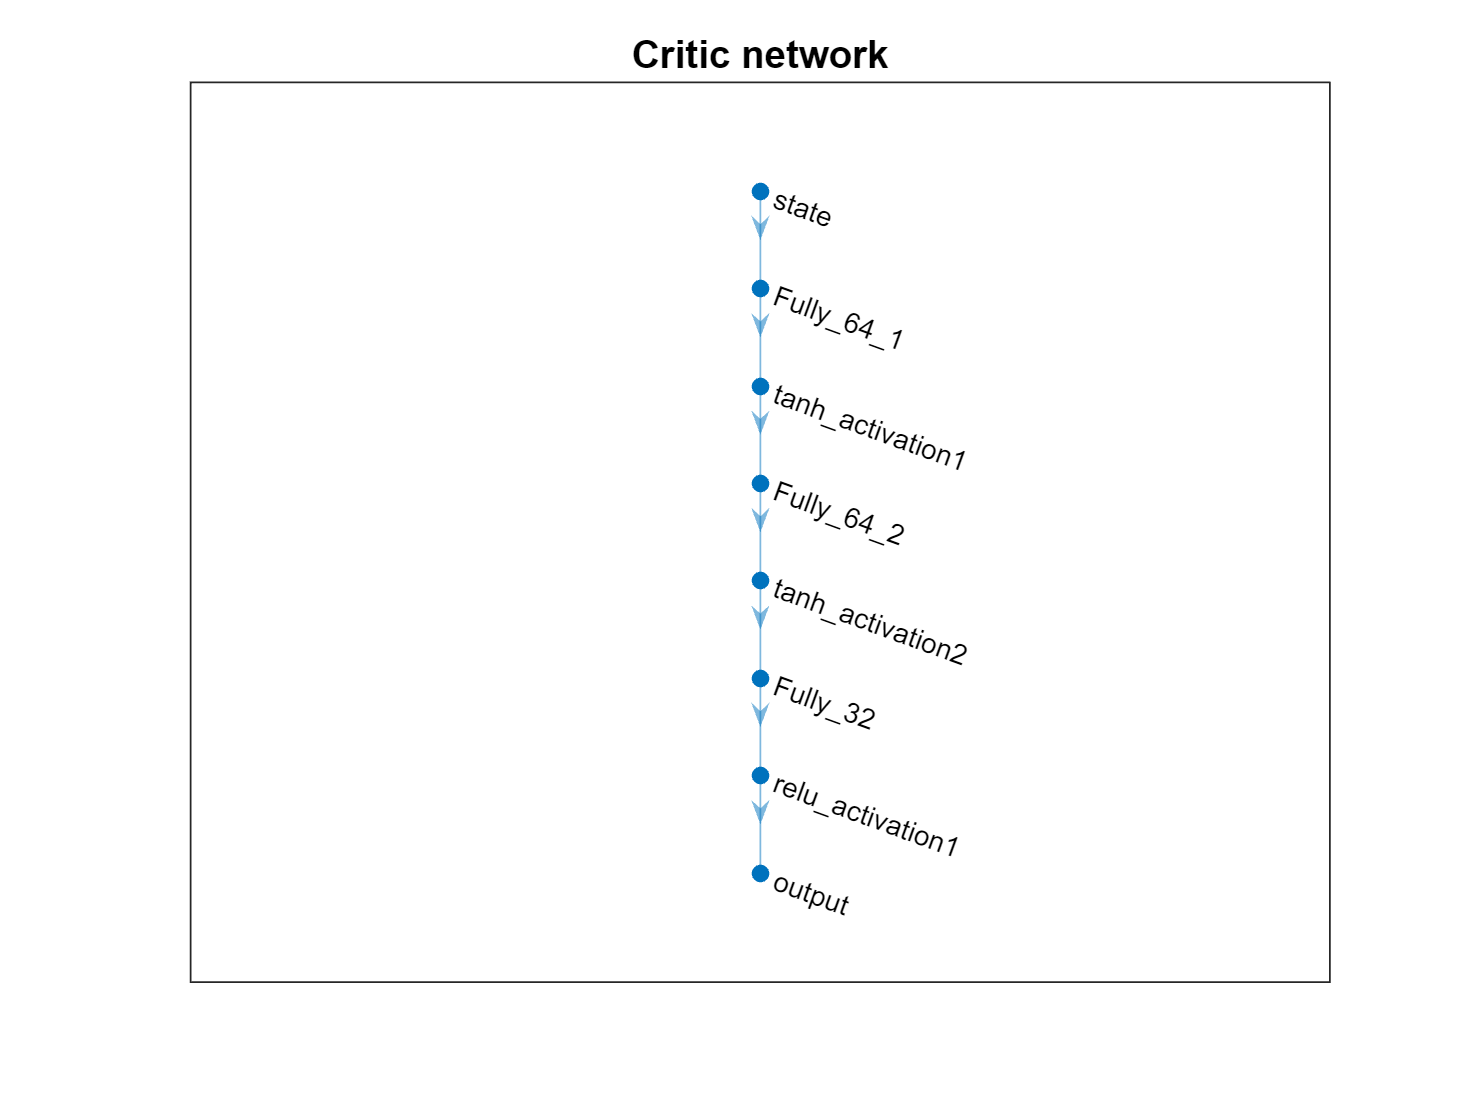

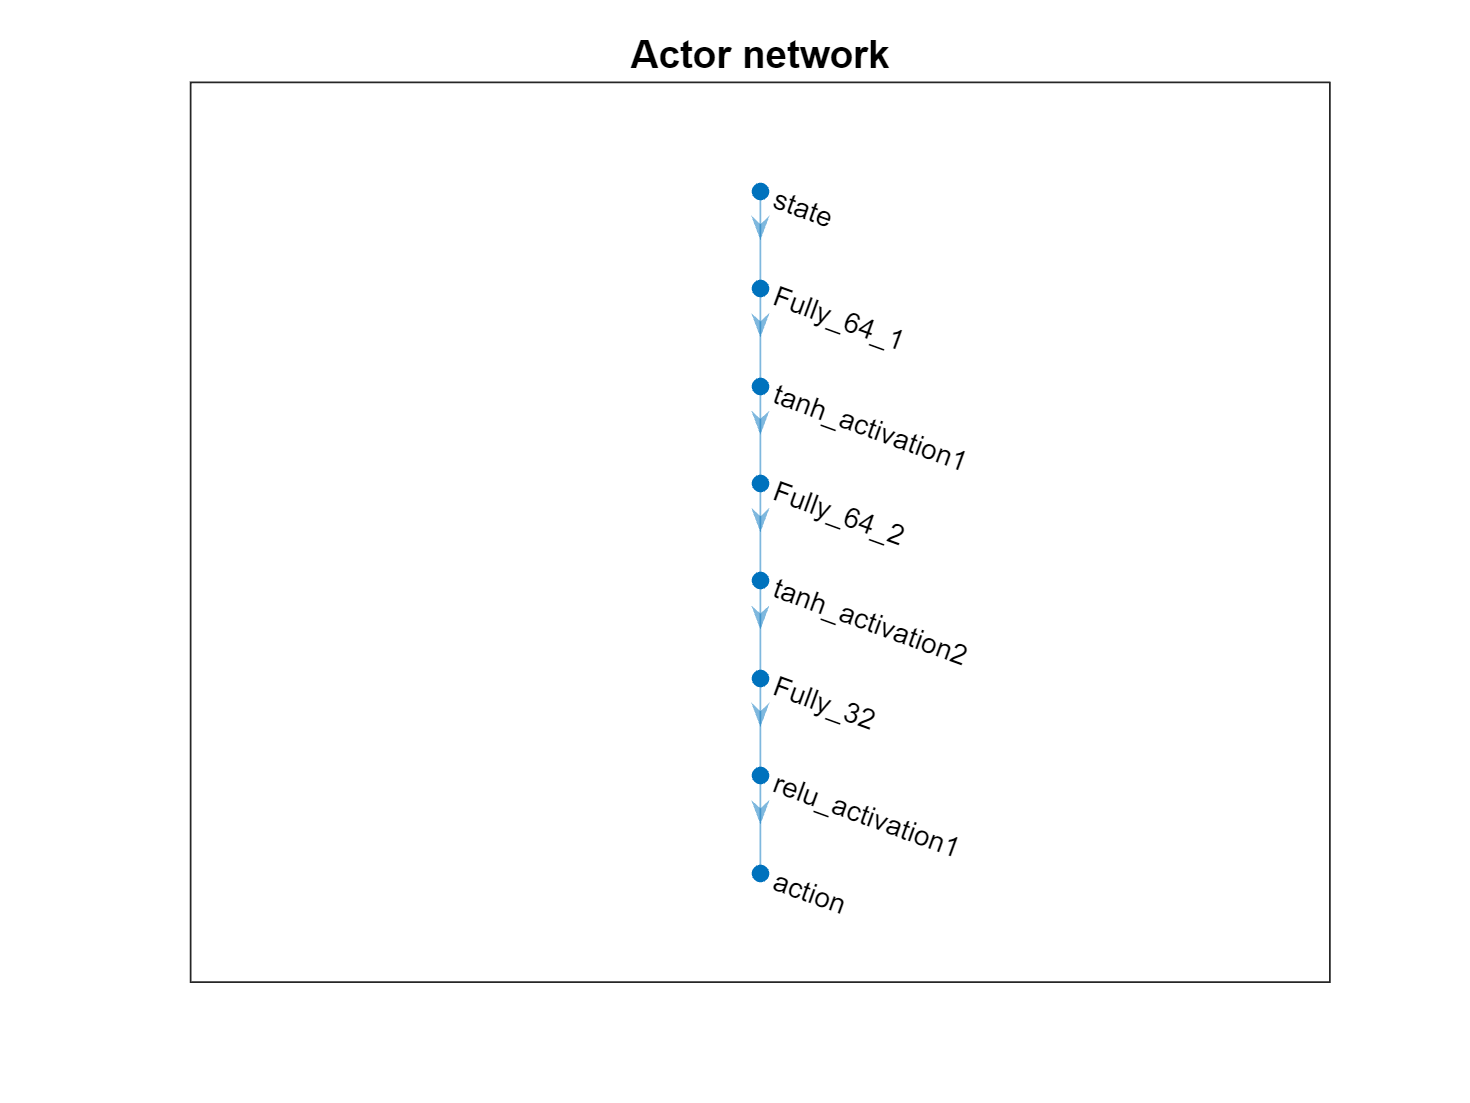

agents = rl.agent.rlPPOAgent.empty(0, numAgents);
for i=1:numAgents
    agents(i) = CreateNetwork(env, i==1); % All agents share the same network architecture, only display first architecture
end

## Agent Training

Either train or load agents

% Define training parameters
trainOpts = rlMultiAgentTrainingOptions(...
    'MaxEpisodes', 2500, ...
    'ScoreAveragingWindowLength',10,...
    StopTrainingCriteria="None",...
    MaxStepsPerEpisode=2597);

doTraining = false;
if doTraining
    trainingStats = train(agents,env,trainOpts);
else
    load agents-competing.mat;
end

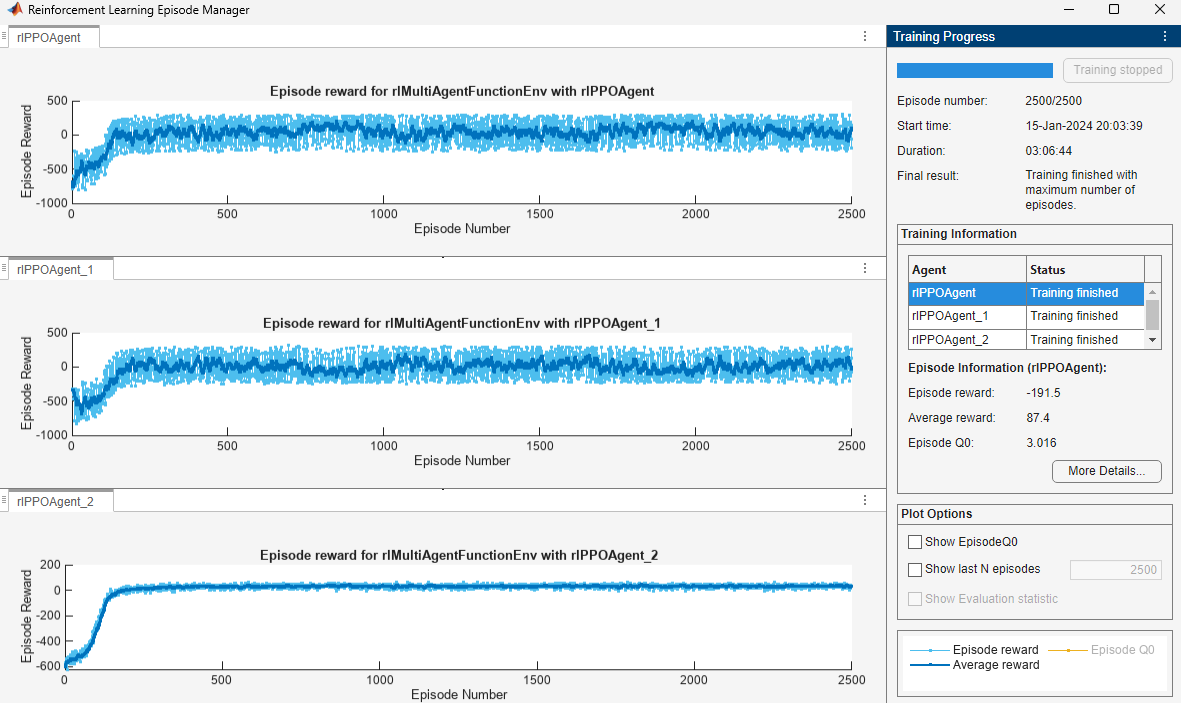

## Simulation on Test data

Compare performance of agents on test data

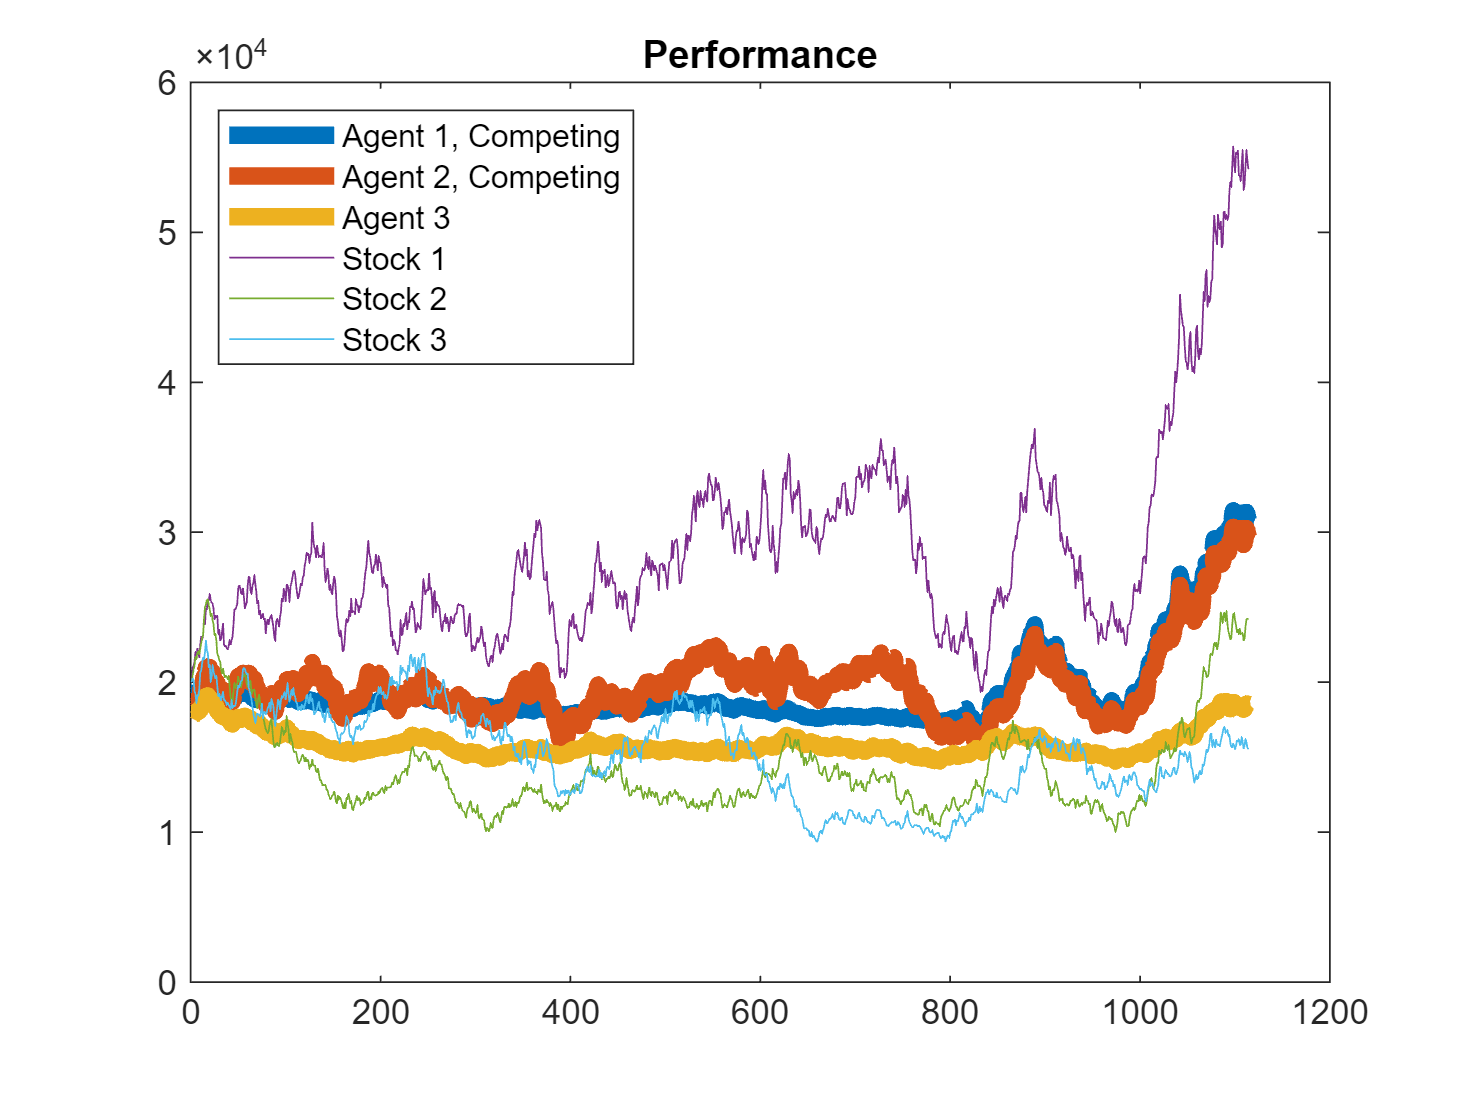

% Define test environment using testData
ResetHandleT = @() myResetFunctionMulti(testData, numAgents);
StepHandleT = @(Action,StockSaved) myStepFunctionMulti(Action,StockSaved,testData,Action_Vectors,false, numAgents);
envT = rlMultiAgentFunctionEnv(ObservationInfo,ActionInfo,StepHandleT,ResetHandleT);
simOpts = rlSimulationOptions('MaxSteps',1113);

% Simulate agents on test environment
experience = sim(envT,agents, simOpts);
GraphPerformance(experience, testData);

*Copyright 2024 The MathWorks, Inc.*[line 130](matlab: opentoline('C:\Program Files\MATLAB\R2023b\toolbox\rl\rl\+rl\+env\@AbstractEnv\sim.m',130,0))